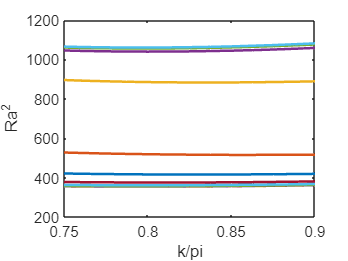

clear all
close all
clc


for ind=1:13
    if ind==1
        load sigma_H=-3.mat
    end
    if ind==2
        load sigma_H=-4.mat
    end
    if ind==3
        load sigma_H=-2.mat
    end
    if ind==4
        load sigma_H=-1.5.mat
    end
    if ind==5
        load sigma_H=-1.mat
    end
    if ind==6
        load sigma_H=-0.5.mat
    end
    if ind==7
        load sigma_H=1.mat
    end
    if ind==8
        load sigma_H=0.5.mat
    end
    if ind==9
        load sigma_H=10.mat
    end
    if ind==10
        load sigma_H=100.mat
    end
    if ind==11
        load sigma_H=1000.mat
    end
    if ind==12
        load sigma_H=3.5.mat
    end
    if ind==13
        load sigma_H=10000.mat
    end
    l=1;
    l2=1;
    for j=1:length(kk)
        flag=0;
        n=1;
        while n<=length(RR)-1 && flag==0
            if (real(sigma(n,j))<0 && real(sigma(n+1,j))>0 && abs(imag(sigma(n+1,j)))<10^(-6)) || (real(sigma(n,j))>0 && real(sigma(n+1,j))<0 && abs(imag(sigma(n+1,j)))<10^(-6))
                if flag==0
                    realRa(l)=RR(n);
                    realwavenumber(l)=kk(j);
                    l=l+1;
                    flag=1;
                end
            end
            n=n+1;
        end
    end
    plot(realwavenumber,realRa.^2,'LineWidth',1.5)
    xlabel('k/pi')
    ylabel('Ra^2')
    hold on
    [Rc(ind),index]=min(realRa.^2);
    wavec(ind)=realwavenumber(index);
    realRa=[];
    realwavenumber=[];

end

HH=10.^[-4 -3 -2 -1.5 -1 -0.5 0 0.5 1 2 3 3.5 4 ];
hold off

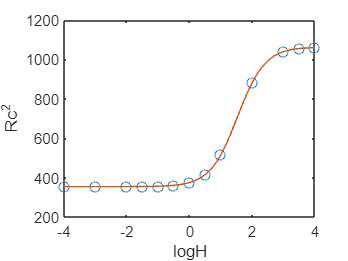

xx = -4:0.1:4;
yy = spline(log10(HH),Rc,xx);
plot(log10(HH),Rc,'o',xx,yy)
xlabel('logH')
ylabel('Rc^2')


save Rc_logH_gamma=0.5.mat Rc wavec